# KF tuning with Grid Search Optimization

clc
clf
clear all
close all
rng(0)

## Parallel computing

if isempty(gcp('nocreate'))
    cluster = parcluster('local');
    parpool(cluster, cluster.NumWorkers);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


p = gcp();
fprintf('Using %d parallel workers\n', p.NumWorkers);

Using 8 parallel workers


## Generate log grid

N_points       = 100; % Grid resolution
N_combinations = N_points^2; % Number of total simulations
lb = -10; % Lower bound for the exponent
ub = 2;   % Upper bound for the exponent
qi_vec = logspace(lb, ub, N_points);
qF_vec = logspace(lb, ub, N_points);

T = combinations(qi_vec, qF_vec);
T.Properties.VariableNames = {'qi', 'qF'};
Q_combinations = table2struct(T);

## Load data

data = load('KF_TuningData.mat').out';

## Grid Search Optimization

cost_results = zeros(N_combinations, 1);

tic
parfor i = 1:N_combinations
    cost_results(i) = KF_simulate(Q_combinations(i), data, false);
end
toc

Elapsed time is 507.661857 seconds.


T.MSE = cost_results;

Sort by increasing cost

[~, idx] = sort(T.MSE, 'ascend');
T_sorted = T(idx, :)

T_sorted = 10000×3 table
        qi            qF           MSE    
    __________    __________    __________

     0.0014175    4.6416e-08    0.00046126
     0.0018738    6.1359e-08    0.00046132
     0.0024771    8.1113e-08    0.00046182
     0.0010723    3.5112e-08    0.00046197
     0.0010723    4.6416e-08     0.0004621
     0.0014175    6.1359e-08    0.00046239
     0.0032745    1.0723e-07    0.00046255
    0.00081113    3.5112e-08    0.00046262
     0.0018738    8.1113e-08    0.00046314
     0.0043288    1.4175e-07    0.00046335
    0.00081113    2.6561e-08    0.00046387
     0.0024771    1.0723e-07    0.00046413
     0.0057224    1.8738e-07    0.00046414
    0.00061359    2.6561e-08    0.00046439
     0.0075646    2.4771e-07    0.00046487
     0.0032745    1.4175e-07    0.00046521


## Plot results

[QI_MAT, QF_MAT] = meshgrid(qi_vec, qF_vec);
qi_flat = QI_MAT(:);
qF_flat = QF_MAT(:);
COST_MAT = reshape(T.MSE, N_points, N_points);
min_cost = T_sorted.MSE(1);
best_qi = T_sorted.qi(1);
best_qF = T_sorted.qF(1);

figure('Name', 'Grid Search Optimization Results', 'Color', 'w', 'Position', [100, 100, 900, 700]);
hold on

Interpolated surface

surf_h = surf(QI_MAT, QF_MAT, COST_MAT, ...
    'EdgeColor', 'none', ...
    'FaceColor', 'interp', ...
    'FaceAlpha', 0.7);

Contour lines

n_niveles = 20; 
[~, h_cont] = contour3(QI_MAT, QF_MAT, COST_MAT, n_niveles, 'k');
h_cont.LineWidth = 1.2;

Constant qi/qF lines

ratios_to_plot = [0.001, 10, 1000]; 

% Pequeño offset en Z para que la línea no quede "enterrada" en la superficie
z_lift = (max(cost_results) - min(cost_results)) * 0.02; 

for r = ratios_to_plot
    % 1. Generar coordenadas X (qi) densas para que la línea se vea suave
    line_qi = logspace(log10(min(qi_flat)), log10(max(qi_flat)), 100);

    % 2. Calcular coordenadas Y (qF) basadas en la relación: qi / qF = r -> qF = qi / r
    line_qF = line_qi / r;

    % 3. Filtrar puntos que caen fuera de tu rango de simulación
    valid_mask = (line_qF >= min(qF_flat)) & (line_qF <= max(qF_flat));
    line_qi = line_qi(valid_mask);
    line_qF = line_qF(valid_mask);

    if ~isempty(line_qi)
        % 4. Interpolación Mágica: Calcular la altura (Costo) en esos puntos exactos
        % Usamos interp2 sobre tus matrices originales
        line_cost = interp2(QI_MAT, QF_MAT, COST_MAT, line_qi, line_qF, 'linear');

        % 5. Graficar la línea sobre la superficie (blanca punteada)
        plot3(line_qi, line_qF, line_cost + z_lift, ...
              'w--', 'LineWidth', 1.5, 'DisplayName', sprintf('Ratio %.2g', r));

        % 6. (Opcional) Agregar etiqueta de texto al final de la línea
        text(line_qi(end), line_qF(end), line_cost(end) + z_lift, ...
             sprintf('  R=%.2g', r), ...
             'Color', 'k', 'BackgroundColor', 'w', 'FontSize', 8, 'Margin', 1);
    end
end

Grid points

scatter_h = scatter3(qi_flat, qF_flat, cost_results, ...
    1, 'k', 'filled', ...
    'MarkerEdgeColor', 'none', ...
    'MarkerFaceAlpha', 0.5);

Minimum value

min_h = plot3(best_qi, best_qF, min_cost, ...
    'rp', 'MarkerSize', 22, ...
    'MarkerFaceColor', 'r', ...
    'LineWidth', 2);

Format

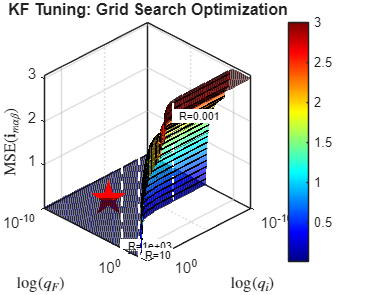

set(gca, 'XScale', 'log', 'YScale', 'log', 'FontSize', 11);

xlabel('$$\log(q_i)$$', 'FontWeight', 'bold', 'Interpreter', 'latex');
ylabel('$$\log(q_F)$$', 'FontWeight', 'bold', 'Interpreter', 'latex');
zlabel('$$\mathrm{MSE}(\mathbf{i}_{m\alpha\beta})$$', 'FontWeight', 'bold', 'Interpreter', 'latex');
title('KF Tuning: Grid Search Optimization', 'FontSize', 12);

colorbar;
colormap(jet);
view(135, 30);
grid on; box on;

## Plot filtering

mask = 1:round(size(T_sorted, 1) * 0.01);
T_sorted.MSE(mask(end));
best_qi = prod(T_sorted(mask, :).qi.^(1/numel(mask)))

best_qi = 0.0887

best_qF = prod(T_sorted(mask, :).qF.^(1/numel(mask)))

best_qF = 2.7929e-06


best_qi = T_sorted.qi(1)

best_qi = 0.0014

best_qF = T_sorted.qF(1)

best_qF = 4.6416e-08

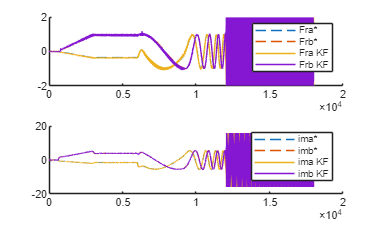

ans = 1.7731


best_qi = 1;
best_qF = 1;

x = struct();
x.qi = best_qi;
x.qF = best_qF;
do_plot = true;
KF_simulate(x, data, do_plot)